# 1D Stuart-Landau dynamics identification with SSMLearn

We will simulate the system 

$\dot{x} =x-x^3$,

delay embed the data and look for a 1D invariant manifold for dimensionality reduction in the observable space. We will fit a polynomial map to the evolution of the reduced coordinates. The transient nature of this problem means that DMD fails to describe the dynamics, whereas the nonlinear reduced dynamics model from SSMLearn can capture the behaviour close to both fixed points 0 and 1.

clearvars
close all

F = @(t,x) x-x.^3;
IC = [1e-3];

tEnd = 20;
dt = 0.04;
nSamp = tEnd/dt+1;

xData = integrateTrajectories(F, tEnd, IC, nSamp)

simulating trajectory 1 of 1...


xData = 1×2 cell array
    {1×501 double}    {1×501 double}


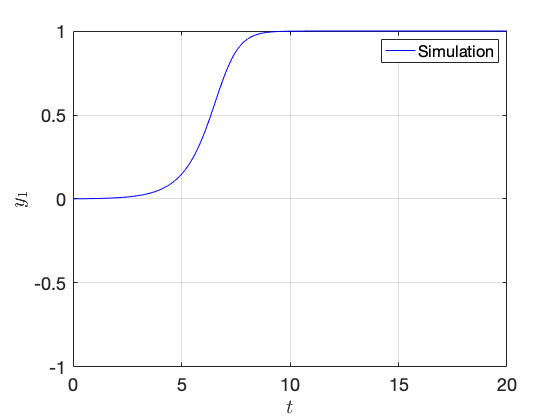

plotTrajectories(xData, 'DisplayName', {'Simulation'})

## Delay embedding

With delay embedding, we stack a number of subsequent snapshots of the signal to produce a higher-dimensional observable space. For a delay embedding dimension of 3, we create the vector


$$\left[\begin{array}{c} y_1(t_k)\\y_2(t_k)\\y_3(t_k) \end{array}\right]=\left[\begin{array}{c} 
x(t_k)\\x(t_k+\Delta t)\\x(t_k+2\Delta t) \end{array}\right]$$


SSMDim = 1;
overEmbed = 0;

yData = coordinatesEmbedding(xData, SSMDim, 'OverEmbedding', overEmbed, 'ShiftSteps', 1)

The 3 embedding coordinates consist of the measured state and its 2 time-delayed measurements.


yData = 1×2 cell array
    {1×499 double}    {3×499 double}


We plot the trajectory in the 3D observable space.

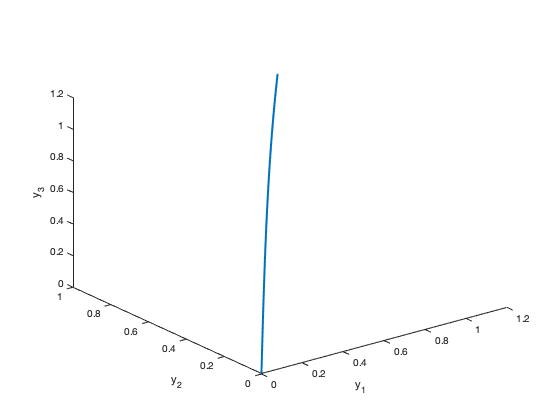

figure
plot3(yData{1,2}(1,:), yData{1,2}(2,:), yData{1,2}(3,:), 'LineWidth', 2);
xlabel('y_1'); ylabel('y_2'); zlabel('y_3');

## Manifold fitting

We use IMGeometry to look for an invariant 1D manifold close to the trajectory.

SSMOrder = 3;
[IMInfo, SSMChart, SSMFunction] = IMGeometry(yData, SSMDim, SSMOrder);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    1.044739e-06    4.441e-16    4.760e-05
    1       2    1.043201e-06    4.411e-09    1.788e-04    6.653e-05
    2       3    9.991417e-07    5.319e-07    9.985e-05    7.638e-04
    3       4    9.353414e-07    6.054e-06    1.971e-05    2.572e-03
    4       5    9.340478e-07    2.334e-09    2.590e-05    6.226e-05
    5       8    9.331690e-07    2.568e-08    2.416e-04    2.149e-04
    6       9    9.180745e-07    5.678e-08    1.327e-04    3.912e-04
    7      10    8.250933e-07    3.570e-06    8.371e-05    3.056e-03
    8      11    4.197711e-07    1.104e-04    5.111e-04    1.696e-02
    9      12    8.802966e-08    1.890e-04    4.503e-04    2.247e-02
   10      13    2.926708e-08    1.770e-05    9.345e-05    6.879e-03
   11      14    3.038428e-09    1.925e-05    4.444e-05    6.739e-03
   12      15    4.734405e-10    2.815e-06    5

The manifold is a curve in the observable space:

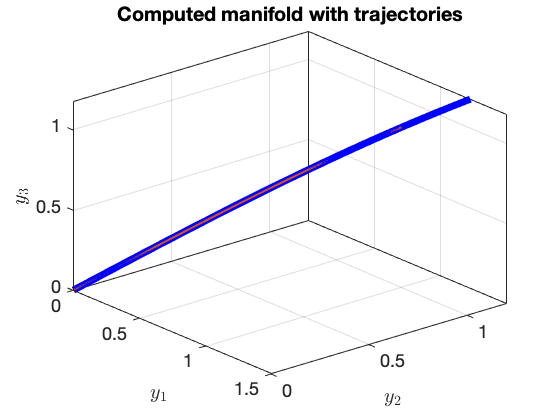

plotSSMWithTrajectories(IMInfo, [1,2,3], yData)
view(50, 30)

We project trajectories onto the eigenspace V as:


$$\eta = V^\top y$$


etaData = projectTrajectories(IMInfo, yData);
RMS = mean(computeParametrizationErrors(IMInfo, yData))

RMS = 8.3028e-06

## Reduced dynamics

Fit a polynomial map to the estimated time derivate of the reduced coordinates


$$\eta^˙ =R\left(\eta \;\right)=R_1\eta +R_2\eta^{2\;} +R_3\eta^3 +\dots \;$$


ROMOrder = 3;
RDInfo = IMDynamicsFlow(etaData, 'R_PolyOrd', ROMOrder);

Estimation of the reduced dynamics...  Done. 


The system $\eta$ is a transformed version of the original $x$ system. The linear part is the same, but the cubic nonlinearities are scaled by a factor 3. The dynamics are conjugate to the original system via the projection onto the manifold.

disp('R coefficients')

R coefficients


disp(RDInfo.reducedDynamics.coefficients)

    0.9996    0.0002   -0.3335



## Evaluation

We advect the initial condition of the trajectory under our reduced dynamics and obtain a reconstruction, which we use to evaluate the quality of our model.

yRec = advect(IMInfo, RDInfo, yData);

RRMSE = mean(computeTrajectoryErrors(yRec, yData))

RRMSE = 2.3489e-04

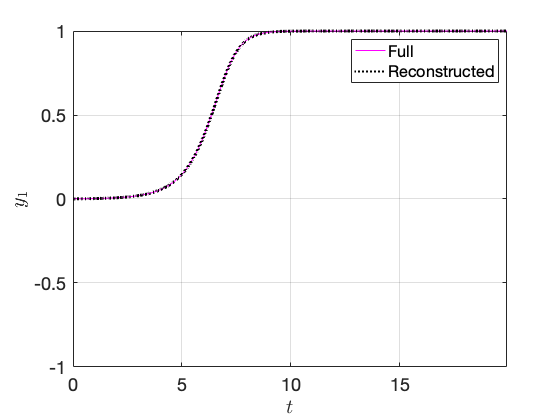


plotTrajectories(yData, yRec, 'm')

## DMD

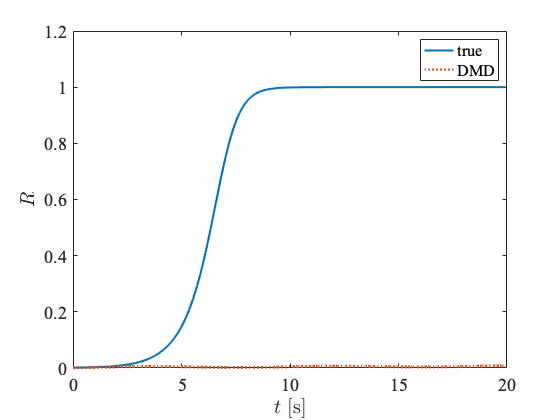

[Phi,omega,lambda,b,Xdmd,t] = DMD(yData{1,2}(:,1:end-1), yData{1,2}(:,2:end), 3, dt);
figure
plot(yData{1,1}, yData{1,2}(1,:), 'DisplayName', 'true', 'LineWidth', 2)
hold on
plot(t, Xdmd(1,:), ':', 'DisplayName', 'DMD', 'LineWidth', 2)
xlabel('$t$ [s]', 'Interpreter', 'latex')
ylabel('$R$', 'Interpreter', 'latex')
legend
set(gca, 'fontname', 'times')
set(gca, 'fontsize', 18)